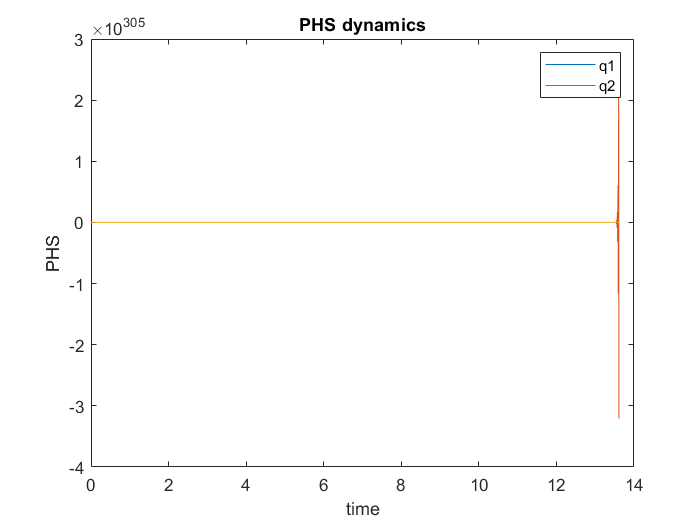

clc
clear
close all

tfinal = 20; dt = 0.001; % simulation parameters

%mass in g, length in m
mb=1.2; ks=700; bs=3; 
mw=0.2; kt=2500; bt=1;
ml=0.2; L=0.20; I=0.5*ml*L^2;
M = [mw+mb I mb;mb I mb;I I I];

G1 = [bt;0;0]; G2 = [-1;0;0]; 
D = diag([bt,0,bs]); G = [0;1;0]; 
A_hat = [-D -eye(3);eye(3) zeros(3)];
B_hat = [G;zeros(3,1)];
lambda = 0; %convergence rate

% initial condition
xr0 = 0; xr=xr0;
x0 = [0;0;0;0;0;0]; x = x0; t = 0; H_sys = 0; 
p10 = mb*x(2); p1 = p10; p20 = ml*x(4); p2 = p20; p30 = mw*x(6); p3 = p30; p=[p1;p2;p3];
q10 = x(1); q1 = q10; q20 = x(3); q2 = q20; q30 = x(5); q3 = q30; q=[q1;q2;q3];
xw = q10 + xr0; xb = q20 + xw; 

%change coordinates
p_hat = p - G1*xr0 ; q_hat = q - G2*xr0;
phs0 = [p_hat;q_hat]; phs = phs0; 

PHS = []; T = []; 
Q = [];P = [];
Xb = []; Xw = []; Xr = []; % initialize memory

while (t <= tfinal)
    T = [T,t]; PHS = [PHS,phs];
    Q = [Q,q]; P = [P,p]; 
    Xb = [Xb,xb]; Xw = [Xw,xw]; Xr = [Xr,xr];
    %xr = sin(w*t); %road profile
    
    %step Input at t = 5s
    if(t>5)
        xr = 1;
    else
        xr=0;
    end

    K = [p_hat(1)+bt*xr; p_hat(2); p_hat(3)];
    KE_hat = 0.5.*K'*inv(M)*K;
    PE_hat = 0.5*kt*(q_hat(1)-xr)^2 + 0.5*ks*q_hat(2)^2;
    H_hat = KE_hat + PE_hat; %energy update

    u = lambda*(H_hat)/2; %control law
    phs = phs + dt*(A_hat*([inv(M)*[phs(1)+bt*xr;phs(2);phs(3)];(kt*(phs(4)-xr));0; phs(5)*ks]) + B_hat*u); %diff eqn
    
    %recorver original coordinates
    q = [phs(4);phs(5);phs(6)]+G2*xr;
    p = [phs(1);phs(2);phs(3)]+G1*xr;
    xw = q(1) + xr;
    xb = q(3) + xw;

    t = t + dt; % time increment
end

figure(1)
plot(T,Q);
ylabel('PHS')
xlabel('time')
legend('q1','q2')
title('PHS dynamics')

figure(2)
%plot(T,Xb); hold on;
%plot(T,Xw); hold on;
plot(T,Xr);
ylabel('states')
xlabel('time')
legend('xb','xr')

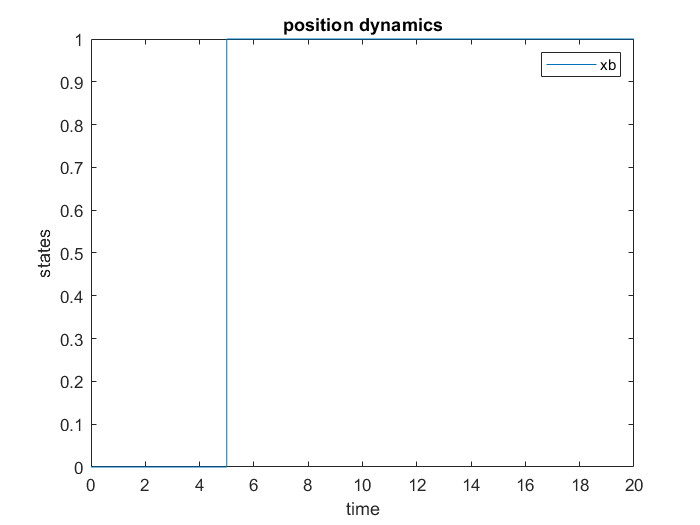

title('position dynamics')
hold off

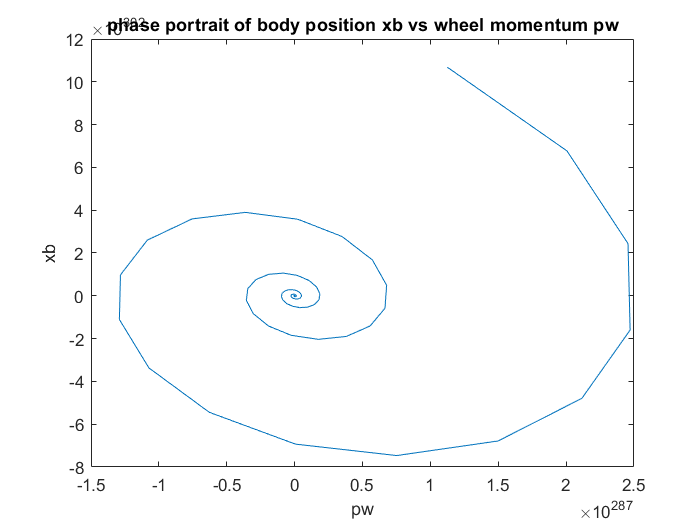

figure(3)
plot(P(1,:),Xb); hold on;
ylabel('xb')
xlabel('pw')
title('phase portrait of body position xb vs wheel momentum pw')
hold off